% 1

L=8;
h=1e-3;

x=-L/2:h:L/2;
N=length(x);
Vx=x.^2;

H=-h^(-2)*(diag(ones(1,N-1),1)+diag(ones(1,N-1),-1)-2*diag(ones(1,N)))+diag(Vx);
EIG=eig(H);
eig15=EIG(1:5);




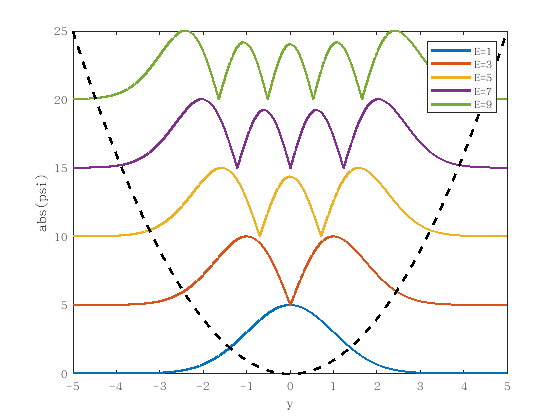

% figure

L=10;
h=1e-3;

x=-L/2:h:L/2;
N=length(x);
Vx=x.^2;

H=-h^(-2)*(diag(ones(1,N-1),1)+diag(ones(1,N-1),-1)-2*diag(ones(1,N)))+diag(Vx);
[VEC,EIG]=eig(H);

eig15=diag(EIG(1:5,1:5));
vec15=abs(VEC(:,1:5));
mv=ones(N,1)*max(vec15);
vec15=vec15./mv;

figure();
hold on;
plot(x,5*(abs(vec15)+ones(N,1)*(0:4)),'linewidth',2);
plot(x,Vx,'k--','linewidth',2);
legend(['E=' num2str(eig15(1))],['E=' num2str(eig15(2))],['E=' num2str(eig15(3))],...
    ['E=' num2str(eig15(4))],['E=' num2str(eig15(5))]);
hold off;
box on;
xlabel('y');ylabel('abs(psi)')

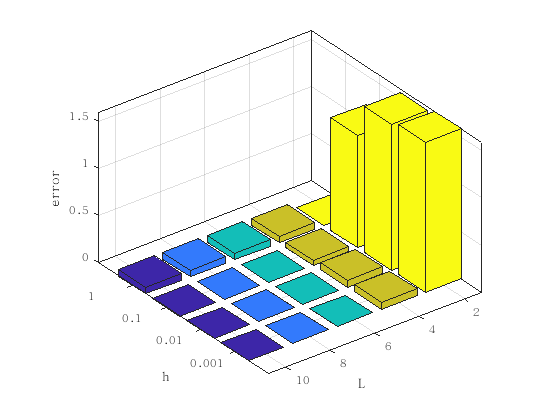

% sensitivity

L=10:-2:2;
h=10.^(0:-1:-3);
[LL,HH]=meshgrid(L,h);
[N1,N2]=size(LL);
E1=zeros(N1,N2);

for ii=1:N2
    for jj=1:N1
        x=-L(ii)/2:h(jj):L(ii)/2;
        N=length(x);
        Vx=x.^2;
        
        H=-h(jj)^(-2)*(diag(ones(1,N-1),1)+diag(ones(1,N-1),-1)-2*diag(ones(1,N)))+diag(Vx);
        EIG=eig(H);
        E1(jj,ii)=EIG(1);
    end
end

bar3(abs(E1-1));
xlabel('L');ylabel('h');zlabel('error');
set(gca,'xticklabel',L,'yticklabel',h);
box on;

% 2

L=8;
h=1e-3;
A=.1;
k=1;
theta=1;

x=-L/2:h:L/2;
N=length(x);
Vx=x.^2+A*cos(k*x+theta);

H=-h^(-2)*(diag(ones(1,N-1),1)+diag(ones(1,N-1),-1)-2*diag(ones(1,N)))+diag(Vx);
EIG=eig(H);
eig15=EIG(1:5);



% 3

%a
a=2;
b=1;
h=.05;
VINF=1000;
fac=.9;

l1=a;
l2=a+b;
x=(-l1/2):h:(l1/2);
y=(-l2/2):h:(l2/2);
[X,Y]=meshgrid(x,y);
N1=length(x);
N2=length(y);

V1=(((Y-fac*b/2).^2+X.^2)>=(fac*fac*a^2/4));
V2=(((Y+fac*b/2).^2+X.^2)>=(fac*fac*a^2/4));
V3=(Y>=(fac*b/2));
V4=(Y<=(-fac*b/2));
V5=(abs(X)>=(fac*a/2));
V=double((V1&V3)|(V2&V4)|V5);

% mesh(X,Y,V);
% axis equal
% xlabel('x');ylabel('y');zlabel('Vnorm')


V=VINF*V;

NN=N1*N2;
H=zeros(NN,NN);
for ii=1:N1
    for jj=1:N2
        loc=(jj-1)*N1+ii;
        cop=[ii-1,jj;ii+1,jj;ii,jj-1;ii,jj+1];
        inm=((cop(:,1)<=N1)&(cop(:,1)>=1)&(cop(:,2)<=N2)&(cop(:,2)>=1));
        use=find(inm);
        for kk=1:length(use)
            ulo=(cop(use(kk),2)-1)*N1+cop(use(kk),1);
            H(loc,ulo)=1;
        end
    end
end
H=H-diag(sum(H));
H=-H/2/h^2;

for ii=1:N1
    for jj=1:N2
        loc=(jj-1)*N1+ii;
        H(loc,loc)=H(loc,loc)+V(jj,ii);
    end
end

[VEC,EIG]=eig(H);

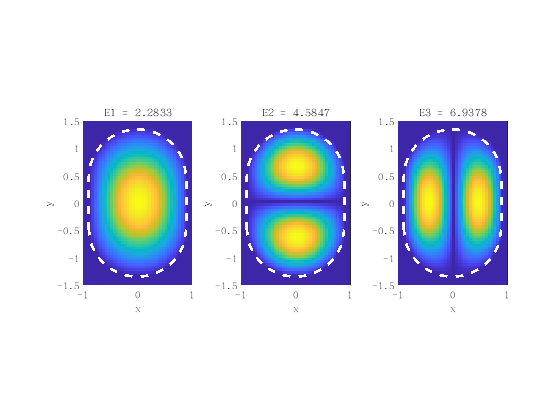

% figure

eig13=diag(EIG(1:3,1:3));
vec13=abs(VEC(:,1:3));

PHI1=zeros(N1,N2);
PHI2=zeros(N1,N2);
PHI3=zeros(N1,N2);

for ii=1:NN
    PHI1(ii)=vec13(ii,1);
    PHI2(ii)=vec13(ii,2);
    PHI3(ii)=vec13(ii,3);
end

figure();
subplot(1,3,1)
hold on;
pcolor(X,Y,PHI1');
shading flat
plot(fac*[x x(end:-1:1) x(1)],fac*[-b/2-sqrt(a^2/4-x.^2) ...
    b/2+sqrt(a^2/4-x.^2) -b/2],'w--','linewidth',2);
hold off;
axis equal
axis([-a/2 a/2 -a/2-b/2 a/2+b/2]);
box on;
xlabel('x');ylabel('y');zlabel('Psi');
title(['E1 = ' num2str(eig13(1))]);

subplot(1,3,2)
hold on;
pcolor(X,Y,PHI2');
shading flat
plot(fac*[x x(end:-1:1) x(1)],fac*[-b/2-sqrt(a^2/4-x.^2) ...
    b/2+sqrt(a^2/4-x.^2) -b/2],'w--','linewidth',2);
hold off;
axis equal
axis([-a/2 a/2 -a/2-b/2 a/2+b/2]);
box on;
xlabel('x');ylabel('y');zlabel('Psi');
title(['E2 = ' num2str(eig13(2))]);

subplot(1,3,3)
hold on;
pcolor(X,Y,PHI3');
shading flat
plot(fac*[x x(end:-1:1) x(1)],fac*[-b/2-sqrt(a^2/4-x.^2) ...
    b/2+sqrt(a^2/4-x.^2) -b/2],'w--','linewidth',2);
hold off;
axis equal
axis([-a/2 a/2 -a/2-b/2 a/2+b/2]);
box on;
xlabel('x');ylabel('y');zlabel('Psi');
title(['E3 = ' num2str(eig13(3))]);

% b

h=.05;
VINF=1000;

x=-1.5:h:1.5;
y=-2.2:h:.5;
[X,Y]=meshgrid(x,y);
N1=length(x);
N2=length(y);

THE=angle(X+i*Y);
RHO=sqrt(X.^2+Y.^2);
V=double(RHO>(1-sin(THE)));

% mesh(X,Y,V);
% axis equal
% xlabel('x');ylabel('y');zlabel('Vnorm')


V=VINF*V;

NN=N1*N2;
H=zeros(NN,NN);
for ii=1:N1
    for jj=1:N2
        loc=(jj-1)*N1+ii;
        cop=[ii-1,jj;ii+1,jj;ii,jj-1;ii,jj+1];
        inm=((cop(:,1)<=N1)&(cop(:,1)>=1)&(cop(:,2)<=N2)&(cop(:,2)>=1));
        use=find(inm);
        for kk=1:length(use)
            ulo=(cop(use(kk),2)-1)*N1+cop(use(kk),1);
            H(loc,ulo)=1;
        end
    end
end
H=H-diag(sum(H));
H=-H/2/h^2;

for ii=1:N1
    for jj=1:N2
        loc=(jj-1)*N1+ii;
        H(loc,loc)=H(loc,loc)+V(jj,ii);
    end
end

[VEC,EIG]=eig(H);

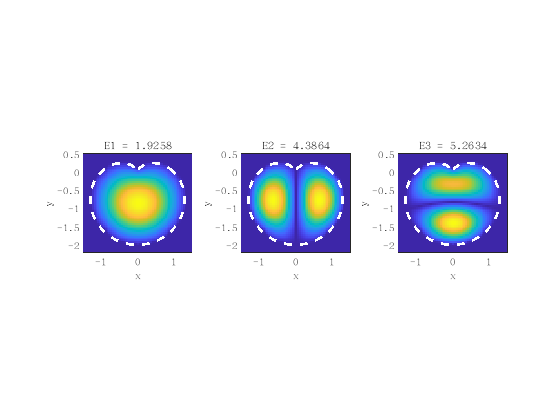

% figure

eig13=diag(EIG(1:3,1:3));
vec13=abs(VEC(:,1:3));

PHI1=zeros(N1,N2);
PHI2=zeros(N1,N2);
PHI3=zeros(N1,N2);

for ii=1:NN
    PHI1(ii)=vec13(ii,1);
    PHI2(ii)=vec13(ii,2);
    PHI3(ii)=vec13(ii,3);
end

the=linspace(0,2*pi,1000);
figure();
subplot(1,3,1)
hold on;
pcolor(X,Y,PHI1');
shading flat
plot((1-sin(the)).*cos(the),(1-sin(the)).*sin(the),'w--','linewidth',2);
hold off;
axis equal
axis([-1.5 1.5 -2.2 .5])
box on;
xlabel('x');ylabel('y');zlabel('Psi');
title(['E1 = ' num2str(eig13(1))]);

subplot(1,3,2)
hold on;
pcolor(X,Y,PHI2');
shading flat
plot((1-sin(the)).*cos(the),(1-sin(the)).*sin(the),'w--','linewidth',2);
hold off;
axis equal
axis([-1.5 1.5 -2.2 .5])
box on;
xlabel('x');ylabel('y');zlabel('Psi');
title(['E2 = ' num2str(eig13(2))]);

subplot(1,3,3)
hold on;
pcolor(X,Y,PHI3');
shading flat
plot((1-sin(the)).*cos(the),(1-sin(the)).*sin(the),'w--','linewidth',2);
hold off;
axis equal
axis([-1.5 1.5 -2.2 .5])
box on;
xlabel('x');ylabel('y');zlabel('Psi');
title(['E3 = ' num2str(eig13(3))]);

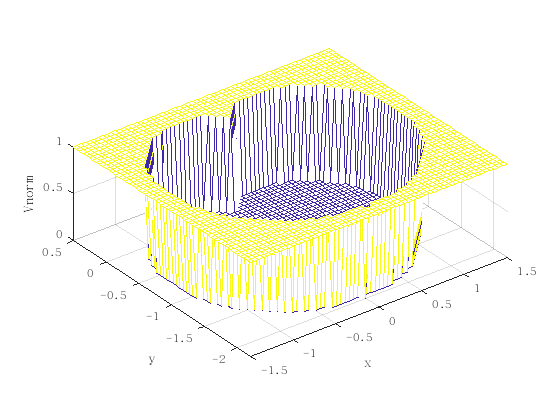

figure()
mesh(X,Y,V/1000);
axis equal
xlabel('x');ylabel('y');zlabel('Vnorm')

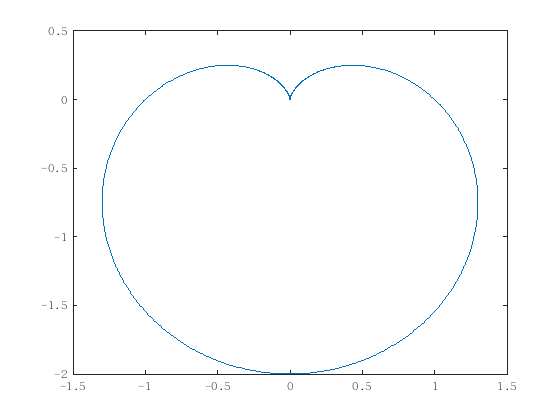

figure()
the=linspace(0,2*pi,1000);
x=(1-sin(the)).*cos(the);
y=(1-sin(the)).*sin(the);
plot(x,y);